# Mass-spring-dampers and aeroplane landing behaviour

This livescript is a brief manual in support of the app ***aeroplanelanding_and_behaviour.mlapp***.   This is a simple interface to understand the modelling and behaviour of simple mass-spring-damper models, but with a mildy humourous animation to help with student engagement.

A mass-spring-damper is a simplified model of typical suspension systems and the landing of an aircraft is a nice example of suspension in action. We want to determine whether passengers are comfortable. This app allows users to investigate the impact of different masses, dampers and springs on the landing behaviour; implicitly this is linked to a understanding of under-damped 2nd order responses.

More detailed notes on 2nd order behaviours for under-damped models is ine the livescript: ***secondordermodels_and_underdamping.mlx ***and also*** secondordermodels_in_matlab.mlx.***

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Preliminaries on under-damped 2nd order responses

- Aeroplane landing behaviour

- Interface and user interaction

## **1. Preliminaries on under-damped 2nd order responses**

A suspension system can be represented as mass-spring-damper (MSD) model. In this app, we focus on the under-carriage of a landing aircraft which is, in effect, treated like a suspension system and thus a MSD model.

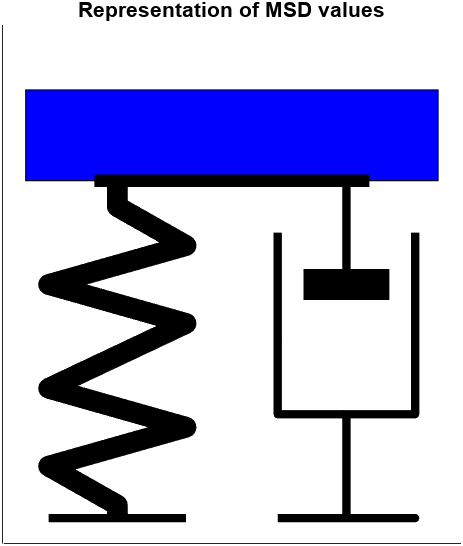  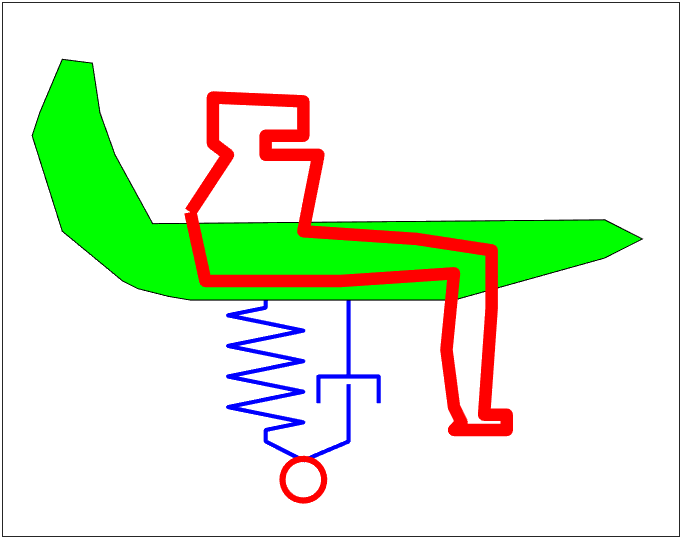

Let the ODE model for a mass-spring-damper system (Mass *M*, damping *B* and spring stiffness *k, *spring extension* x*) and Laplace equivalent be given as:

$M\frac{d^2 x}{dt^2 }+B\frac{\textrm{dx}}{\textrm{dt}}+\textrm{kx}=f$    or    $X\left(s\right)=\frac{1}{a_2 s^2 +a_1 s+a_0 }\times \frac{1}{s}$  where ***f***  the applied force is a unit step for simplicity in this section, but assumed as zero in the aeroplane scenario (so *f* ignored later in this file).

The characteristic under-damped or normalised form for the denominator is given as: $p\left(s\right)=M\left(s^2 +2\zeta \omega_n s+\omega_n^2 \right)$ where $\zeta \;$is the damping ratio, assumed between 0 and 1 for an under-damped system and $\omega_n$ is the natural frequency. Core characteristics are:

- Damping ratio  $\zeta \;$ and relative magnitudes of overshoots (decay rate). $\textrm{First}\;\textrm{overshoot}\;\left(%\right)=100\;e^{-\frac{\zeta \pi }{\sqrt{1-\zeta^2 }}}$

- Time to first peak in response (half the oscillation period). $T_1 =\frac{\pi w_n }{\sqrt{1-\zeta^2 }}$

- Effective time constant. $T=\frac{2M}{B}=\frac{1}{\zeta w_n }$

These can be seen in the figure here.

% define parameters
M=10^6;
B=M/3;
k=M;
p=[M,B,k]; 
r= roots(p); 

wn = 1

p1 = max(real(r));

zeta = 0.1667

wn=sqrt(k/M);
zeta = (B/M)/(2*wn);

T1 = 3.1862

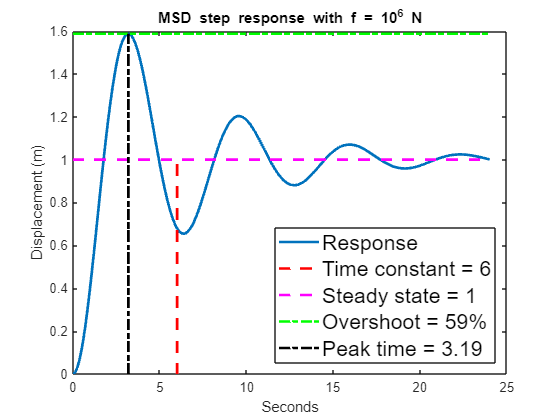

T=-1/p1;
T1 = pi/(wn*sqrt(1-zeta^2));
Steadystate= 1/k;
Slowesttimeconstant= T;
runtime = round(4*T);
overshoot = exp(-zeta*pi/sqrt(1-zeta^2));

% Solve for behaviour with standard forced step response
syms y(t);
Dy = diff(y);
D2y=diff(Dy);
y=dsolve(M*D2y+B*Dy+k*y == 1,y(0)==0, Dy(0)==0);
tt=linspace(0,runtime,201);
yt = eval(subs(y,tt))*10^6;

% Plot core characteristics
figure
clf
plot(tt,yt,'linewidth',2); 
hold on
plot([T,T],[0,10^6/k],'r--','LineWidth',2)
plot([0,runtime],10^6*[1/k,1/k],'m--','LineWidth',2)        
maxyt = max(yt);
plot([0,runtime],[1,1]*maxyt,'g-.','LineWidth',2)   
plot([T1,T1],[0,maxyt],'-.k','Linewidth',2)
kk=legend('Response',['Time constant = ',num2str(round(T,2))],['Steady state = ',num2str(round(Steadystate*10^6,2))],['Overshoot = ',num2str(round(100*overshoot,0)),'%'],['Peak time = ',num2str(round(T1,2))],'Location','southeast');
set(kk,'fontsize',16);
title('MSD step response with f = 10^6 N')

xlabel('Seconds')
ylabel('Displacement (m)')


## 2. Aeroplane landing behaviour 

A subtle difference is needed in the solution of the differential equation model. We assume no applied force, but the aeroplane has a non-zero vertical velocity* v* when it hits the tarmac. Hence we need to solve the following ODE. We take *x* as spring displacement but this is also a measure of displacement relative to the tarmac. 


$$M\frac{d^2 x}{dt^2 }+B\frac{\textrm{dx}}{\textrm{dt}}+\textrm{kx}=0,\;x\left(0\right)=0,\overset{\ldotp }{x\left(0\right)} =v$$


The generic behaviour characterisation and convergence will be the same as in section 1, but the transients will differ. Moreover, we are also interested in the acceleration because passenger comfort will be linked not only to the magnitude and frequency of oscillation, but also the the 'g' forces experienced.

Both the displacement and acceleration can be determined and plotted in a straightforward manner, noting that the initial vertical velocity is negative.

disp('Section 2 below: Aeroplane landing')

Section 2 below: Aeroplane landing


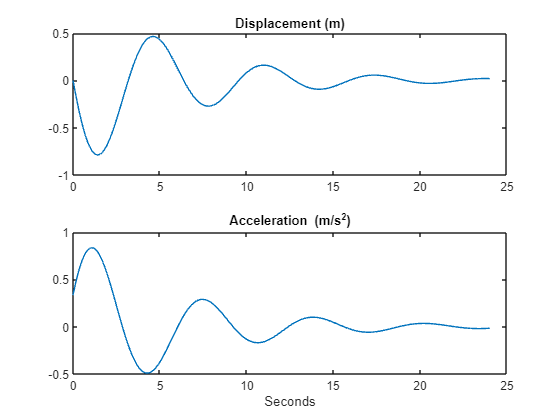


% Find landing behaviour
v0=-1;
syms y(t);
Dy = diff(y);
D2y=diff(Dy);
y=dsolve(M*D2y+B*Dy+k*y == 0,y(0)==0, Dy(0)== v0);
y2 = diff(diff(y)); % 2nd derivative
tt=linspace(0,runtime,201);
yt = eval(subs(y,tt));
accn = eval(subs(y2,tt));

% Plot the results
figure
subplot(211)
plot(tt,yt)
title('Displacement (m)')
subplot(212)
plot(tt,accn);
title('Acceleration (m/s^2)')
xlabel('Seconds')

## 3. Interface and user interaction

The initial image shows a passenger in an airframe and the suspension system as the plane comes into land. 

The sliders are used to select the desired MSD parameters. When these are changed, the image in the top right changes to represent the relative magnitudes of the parameters (that is, relative to the slider scales). Thus one can visualise increasing aeroplane mass, increasing spring stiffness and so forth.

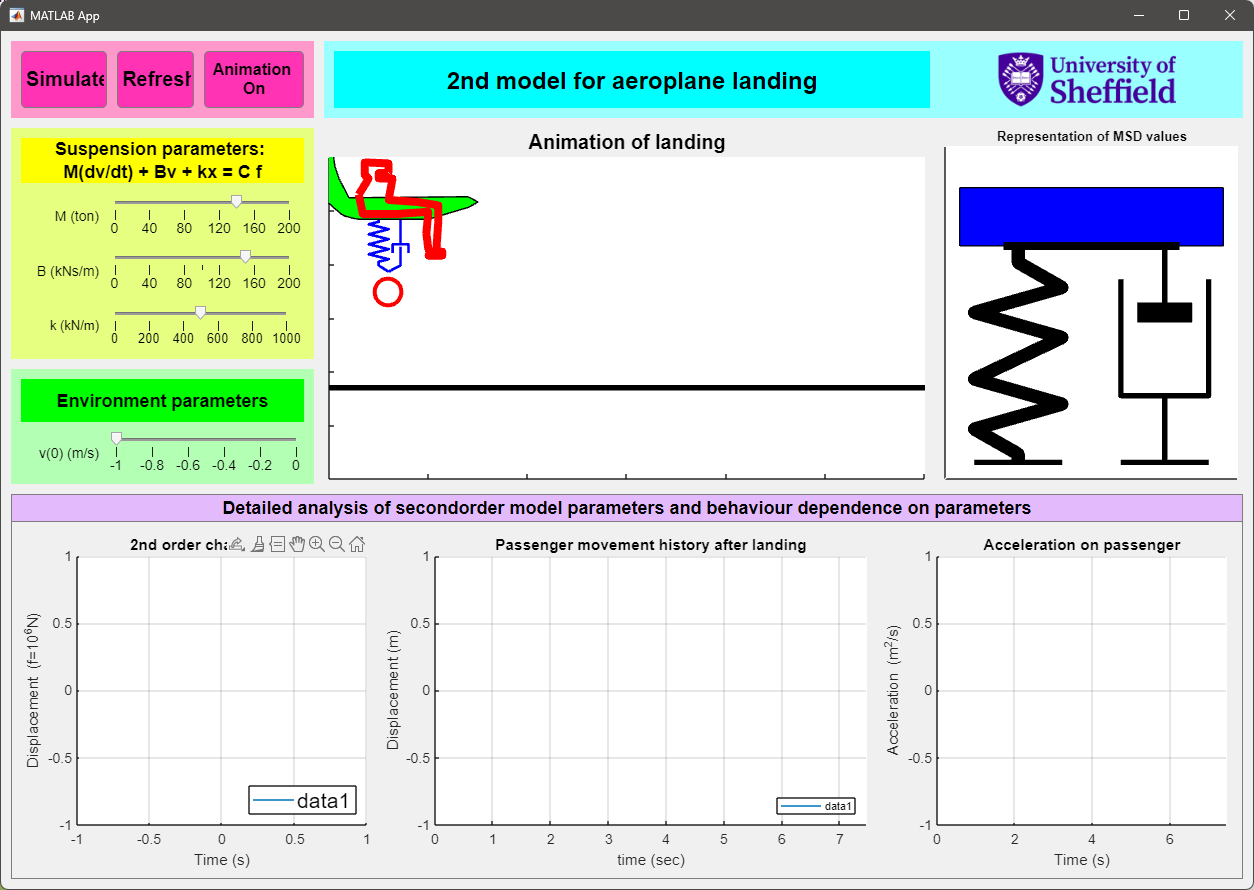

The simulate button activates the animation, with the aeroplane coming into land and then bouncing up and down due to the suspension. The animation runs for about 10 seconds to show the responses in the current scenario; this includes animation of the line plots.

- Users can deploy multiple different parameter choices and overlay the responses in order to investigate the impact of systematic parameter changes.

- The parameters can only take a finite number of discrete values to avoid excessive decimal places and make it easier for the user to achieve repeatability.

- To refresh and begin again, use the refresh button.

- You can turn off the animation to give quicker results using the 'animation/no animation' button.